**Carrega una imatge i visualitza-la**

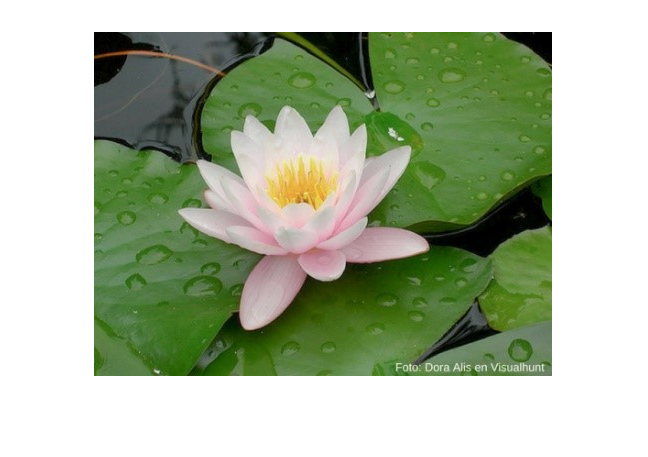

[file,path] = uigetfile('*.*');
if isequal(file,0)
   disp('User selected Cancel');
else
   I = imread(fullfile(path,file));
   [f c nChannels] = size(I);
   if nChannels ~= 3
       disp('You have to choose a RGB image as input');
       % ADD HERE ALL THE CODE OF SECTIONS ABOVE
   end
end

% Display original image
imshow(I);

**Obtenint el rectangle de l'objecte a segmentar**

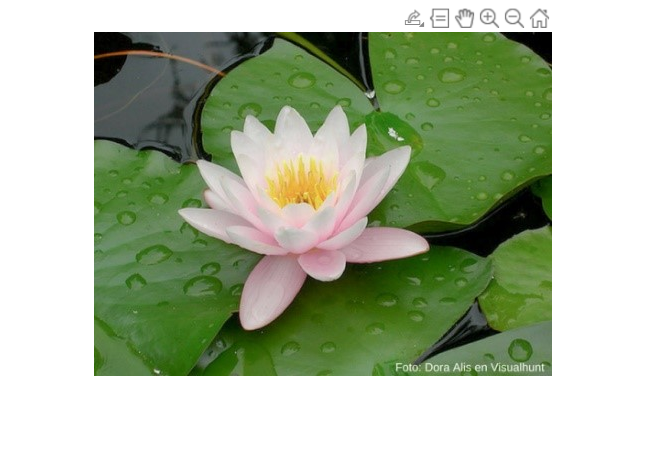

imshow(I);
rect = getrect(); % rect és un array tq [xmin ymin width height]

**Obtenir la imatge HSV i executant el k-means**

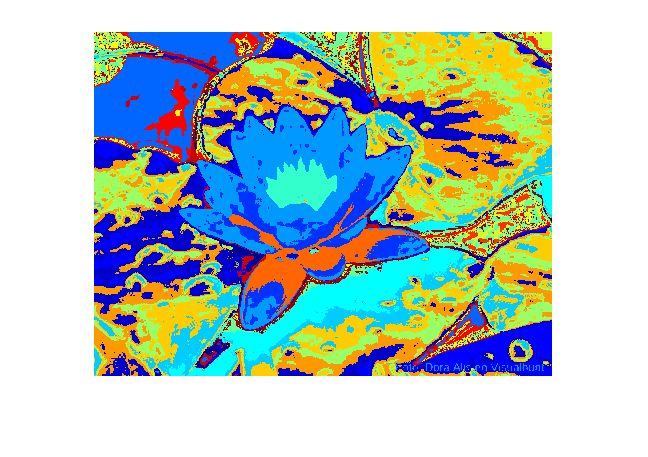

hsv = rgb2hsv(I);
O = reshape(hsv,f*c,3);
k = 20;
C = kmeans(O,k);
IC = reshape(C,f,c);
rgb = label2rgb(IC); 
imshow(rgb);

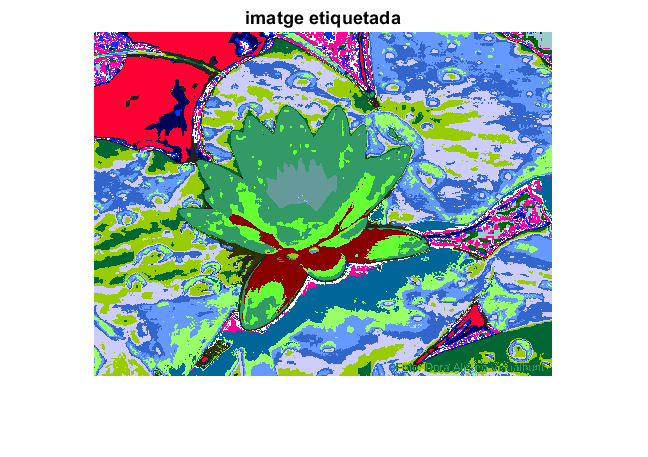

% obtenim la imatge etiquetada pel número cluster
eti=reshape(C,f,c);figure,imshow(eti,[]),colormap(colorcube), title('imatge etiquetada')

**Màscara + creació del vector H**

MASK = zeros(f,c); % generate grid of ones
MASK(rect(2):rect(2)+rect(4),rect(1):rect(1)+rect(3)) = 1;

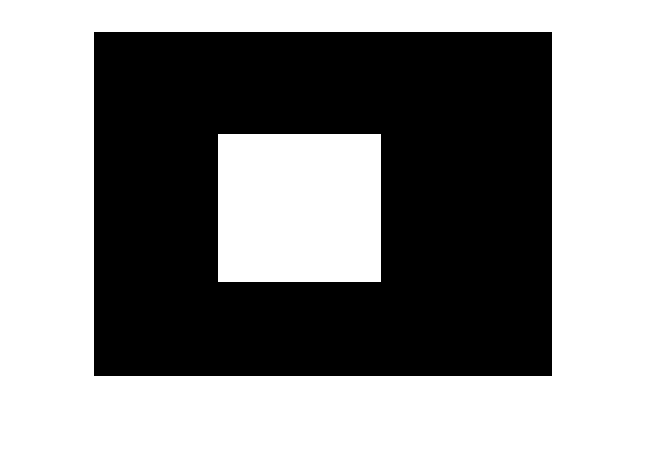

imshow(MASK);

H = [C, MASK(:)];

**Per a cada color de C, fem histogrames dels píxels a dins i a fora del rectangle MASK**

Hist0 = zeros(k); Hist1 = zeros(k);
for i = 1:size(H)
    class = H(i,1);
    if H(i,2) == 0
        Hist0(class) = Hist0(class) + 1;
    else
        Hist1(class) = Hist1(class) + 1;
    end
end

RES = Hist1 > Hist0;

**A partir de RES, decidim quins píxels de H formen part de la figura**

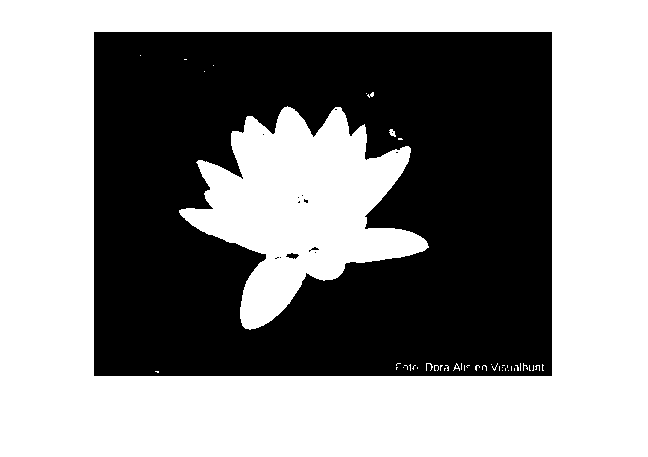

M = zeros(size(H(:,1)));
for i = 1:size(M)
    class = H(i,1);
    if RES(class) == 1
        M(i) = 1;
    end
end

M = reshape(M,f,c); figure, imshow(M,[]);

**Finalment, filtrem el resultat**

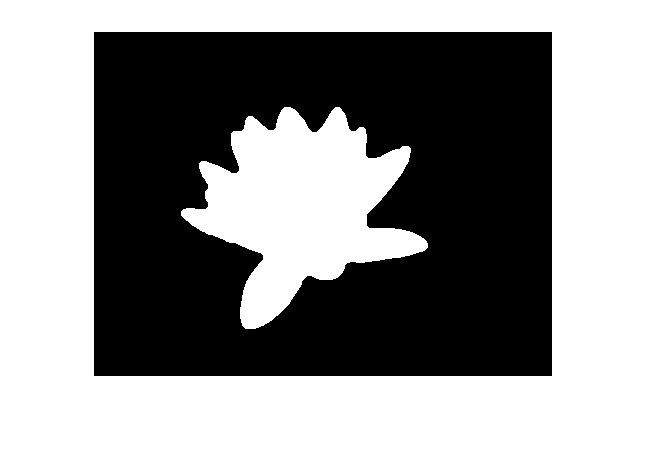

SE=strel('disk',5);
filt=imopen(imclose(M,SE),SE); % filtre OC
figure,imshow(filt)

%montage({M,filt});

**Perfil de l'objecte, en vermell**

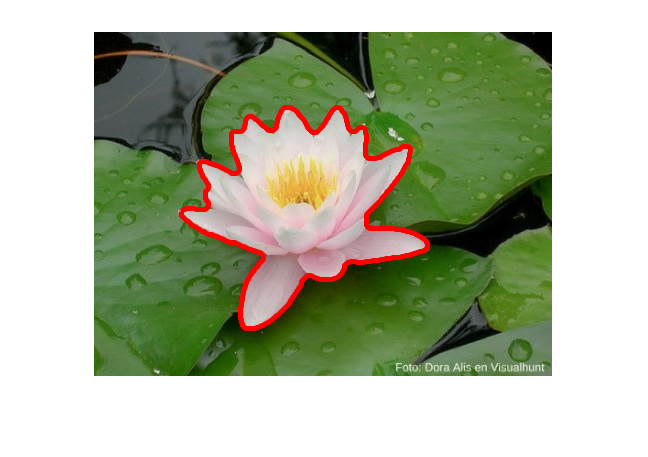

imshow(I);
hold on;
boundaries = bwboundaries(filt);
for k=1:size(boundaries(:,1))
   b = boundaries{k};
   plot(b(:,2),b(:,1),'r','LineWidth',3);
end
hold off;